### Systemic Arteries Model (triangle wave for Qao)

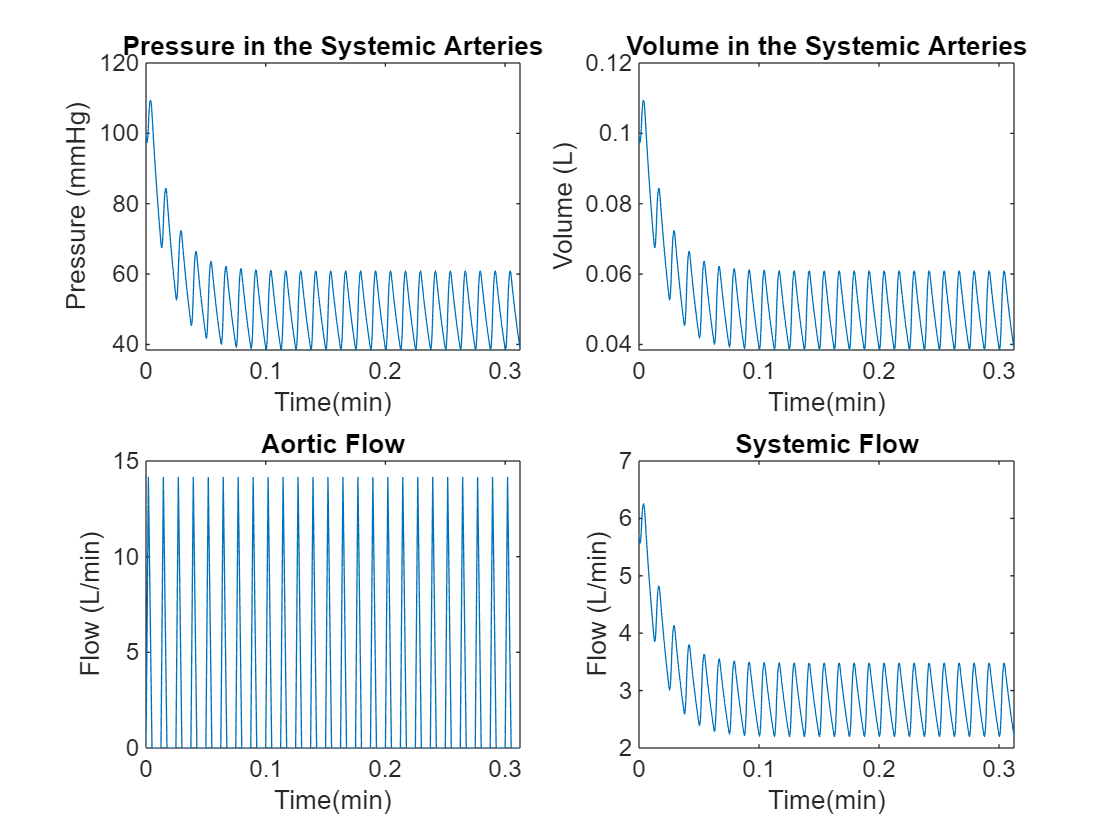

clear;clc;close all 

function Q=Qtriangwave(t,Qmax,T,ts,tmax)
% Find remainder of time between one heartbeat (T) and current time (t)
t1=rem(t,T);
    for ii=1:length(t)
        if t1(ii)<=ts % If remainder less than ts, heart is contracting
            if t1(ii)<=tmax % If remainder less than tmax heart is approaching max flow rate
                Q(ii)=Qmax*t1(ii)/tmax;
            else % If remainder greater than tmax but less than ts heart is reducing flow rate
                Q(ii)=Qmax*(ts-t1(ii))/(ts-tmax);
            end
        else % If remainder is not less than ts heart is in diastole, no flow
            Q(ii)=0;
        end
    end
end 

%Initial Parameters
Psa=100; % Initial Condition for pressure in systemic arteries  (mmHg) 
Rs=17.5; % Resistance of the systemic circuit (mmHg/(L/min)) 
T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
Qmax=14.14;      
% Max flow rate through aorta during systole (L/min) 
Csa=0.001; % Compliance constant for systemic arteries (L/mmHg) 
% Csa was fiddled with to achieve Psa of 120/80 mmHg 
dt=0.0001;        
% Time step (min) 
t=0:dt:25*T;  % Vectorized time (min) 
%% Solve Diff Eq 
for k=1:length(t)-1  % Go from beginning of time to end 
    QAo(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Flow rate at any given point in time 
    Psa(k+1)=Psa(k)+dt*(QAo(k)-Psa(k)/Rs)/Csa;  % Pressure at any given point in time 
end 
% Systemic Flow (Qs)
Qs=Psa/Rs;
% Volume in Systemic Arteries
Vsa=Csa*Psa;

% Plotting
subplot(2,2,1);
plot(t,Psa);
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');
subplot(2,2,2);
plot(t,Vsa);
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');
subplot(2,2,3);
plot(t(1:end-1),QAo); 
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');
subplot(2,2,4);
plot(t,Qs); 
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');

### Left Heart Model

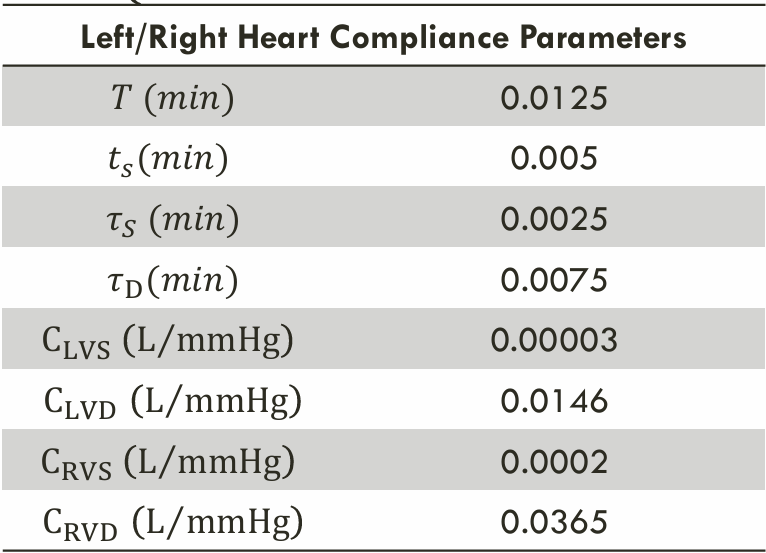

clear;clc;close all 

% Defining parameters and initial conditions
T=0.0125; % min
ts=0.005; % min
tauS=0.0025; % min
tauD=0.0075; % min
CLvs=0.00003; % L/mmHg
CLvd=0.0146; % L/mmHg
CRvs=0.0002; % L/mmHg
CRvd=0.0365; % L/mmHg
Rs=17.5; % mmHg/L/min
Csa=0.001; % L/mmHg
Rmi=0.01; % mmHg*min/L
Rao=0.01; % mmHg*min/L
Ppv=5; % mmHg
Psa=100; % mmHg
Plv=4; % mmHg

% Hemodynamics: dynamic heart compliance
function CV=CV_now(t,T,ts,tauS,tauD,CVS,CVD)
% Compliance of the Ventricle Testing
% CVS and CVD refer to the compliance of either the right or left ventricle during systole and diastole, respectively. 
% CLVS, CRVS, CLVD, and CRVD.

% Remainder of cardiac cycle
tc=rem(t,T);
for ii=1:length(tc) % For every time point that’s in tc
    if tc(ii)<ts % If tc is less than ts, systole
        e=(1-exp(-tc(ii)/tauS))/(1-exp(-ts/tauS));
        CV(ii)=CVD*(CVS/CVD)^e;
    else % If tc is greater than ts, diastole
        e=(1-exp(-(tc(ii)-ts)/tauD))/(1-exp(-(T-ts)/tauD));
        CV(ii)=CVS*(CVD/CVS)^e;
    end
end
end

%% Valves

% I need these functions to be cyclic
tau = @(t) rem(t, T);   % This =0 every multiple of T so it restarts every cycle
u = @(t) double(tau(t) > ts);  % If t>T/3 Systole->Diastole : u=1 , If t>T and t<T/3 Diastole->Systole

% Systole -> AO + PUL open, MI + TRI closed
Spul=@(t) 1-u(t);
Sao=@(t) 1-u(t);

% Diastole -> AO + PUL closed, MI + TRI open
Stri=@(t) u(t);
Smi=@(t) u(t);

%% Continuing left heart isolation

% Time range = 2 cycles
Dt=0.0001;
tspan=0:Dt:2*T; % A smaller step gives better results

for ii=1:length(tspan)-1
    Clv_now=CV_now(tspan(ii),T,ts,tauS,tauD,CLvs,CLvd);
    Clv_future=CV_now(tspan(ii+1),T,ts,tauS,tauD,CLvs,CLvd);
    Psa(ii+1)=Dt*(Sao(tspan(ii))*(Plv(ii)-Psa(ii))/Rao - Psa(ii)/Rs)/Csa + Psa(ii);
    Plv(ii+1)=(Dt*(Smi(tspan(ii))*(Ppv-Plv(ii))/Rmi - Sao(tspan(ii))*(Plv(ii)-Psa(ii))/Rao) + Plv(ii)*Clv_now)/Clv_future;
end

### VALVES

% State of valves -> open (1) or closed (0)

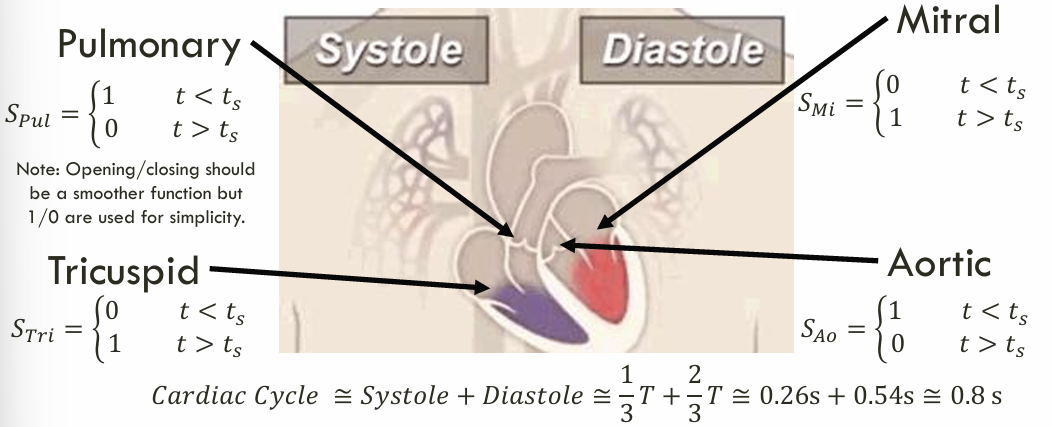

Initial parameters:

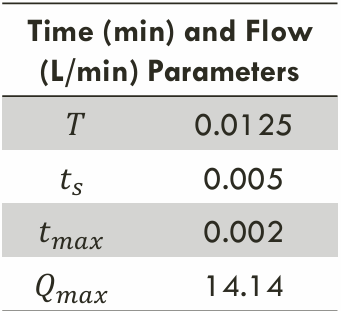

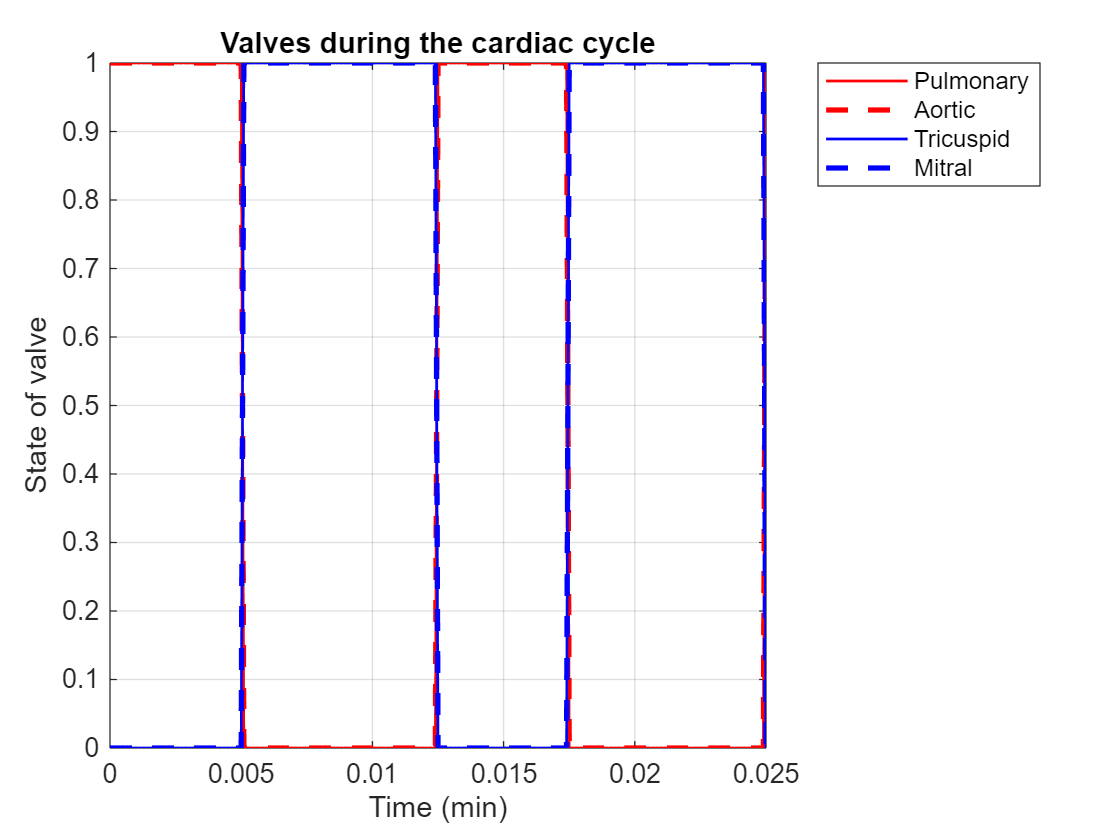

% Initial parameters
ts=0.005;
T=0.0125;
tspan=0:0.0001:2*T; % A smaller step gives better results

% I need these functions to be cyclic
tau = @(t) rem(t, T);   % This =0 every multiple of T so it restarts every cycle
u = @(t) double(tau(t) > ts);  % If t>T/3 Systole->Diastole : u=1 , If t>T and t<T/3 Diastole->Systole

% Systole -> AO + PUL open, MI + TRI closed
Spul=@(t) 1-u(t);
Sao=@(t) 1-u(t);

% Diastole -> AO + PUL closed, MI + TRI open
Stri=@(t) u(t);
Smi=@(t) u(t);

% Plotting to check
plot(tspan,Spul(tspan),'-r','LineWidth',1);
hold on
plot(tspan,Sao(tspan),'--r','LineWidth',2);
plot(tspan,Stri(tspan),'b','LineWidth',1);
plot(tspan,Smi(tspan),'--b','LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('State of valve');
title('Valves during the cardiac cycle');
legend('Pulmonary','Aortic','Tricuspid','Mitral','Location','bestoutside');
hold off

## Probando

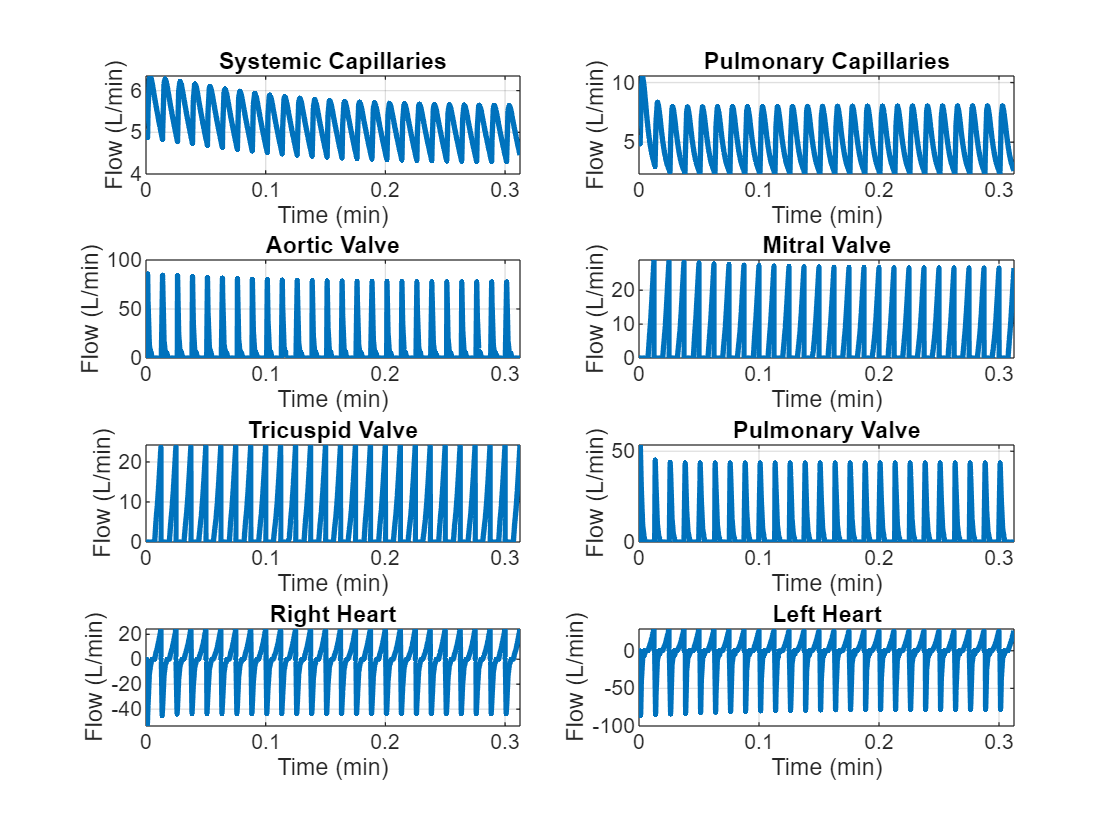

clear; clc; close all;

%% Systemic Arteries -> Systemic Veins -> Right Heart -> Pulmonary Arteries -> Pulmonary Veins -> Left Heart ->  start over

%% INITIAL PARAMETERS

% Time-related parameters (min)
T = 0.0125; % Heart period → 80 bpm
ts = 0.005; % Systole duration
dt = 1e-6; % Time step
t = 0:dt:25*T; % Simulate 25+ beats
tauS=0.0025; % Systolic time constant
tauD=0.0075; % Diastolic time constant

% Compliance (L/mmHg)
Csa = 0.0015*1.2; % Compliance constant for systemic arteries 
Csv=1.75; % Compliance constant for systemic veins
Cpa=0.004; % Compliance constant for pulmonary arteries
Cpv=0.08; % Compliance constant for pulmonary veins 
CRVS=0.0002; % RV systolic compliance 
CRVD=0.0365; % RV diastolic compliance 
CLVS = 0.00003; % LV systolic compliance 
CLVD = 0.0146; % LV diastolic compliance 

% Resistance (mmHg/(L/min)) 
Rs  = 17.5*1.107; % Systemic vascular resistance
Rp= 1.79; % Pulmonary vascular resistance
Rti=0.01; % Tricuspid valve resistance 
Rpo=0.01; % Pulmonary valve resistance
Rmi = 0.01; % Mitral valve resistance
Rao = 0.01; % Aortic valve resistance

%% PREALLOCATING

% Pressures (mmHg)
Psa=zeros(length(t),1); Psa(1)=100; % Pressure in systemic arteries
Psv=zeros(length(t),1); Psv(1)=2; % Pressure in systemic veins 
Ppa=zeros(length(t),1); Ppa(1)=15; % Pressure in pulmonary arteries 
Ppv=zeros(length(t),1); Ppv(1)=5; % Pressure in pulmonary veins 
Prv=zeros(length(t),1); Prv(1)=2; % Right ventricular pressure
Plv=zeros(length(t),1); Plv(1)=5; % Left ventricular pressure

% Volumes (L)
Vsa=zeros(length(t)-1,1); Vsa(1)=1; % Volume in systemic arteries
Vsv=zeros(length(t)-1,1); Vsv(1)=3.5; % Volume in the systemic veins
Vpa=zeros(length(t)-1,1); Vpa(1)=0.1; % Volume in the pulmonary arteries
Vpv=zeros(length(t)-1,1); Vpv(1)=0.4; % Volume in the pulmonary veins
Vrv=zeros(length(t),1); % Right ventricular volume 
Vlv=zeros(length(t),1); % Left ventricular volume

% Flows (L/min)
Qs=zeros(length(t)-1,1); % Systemic Capillaries Flow  
Qp=zeros(length(t)-1,1); % Pulmonary Capillaries Flow
Qtri=zeros(length(t)-1,1); % Tricuspid inflow
Qpul=zeros(length(t)-1,1); % Pulmonic outflow
Qr=zeros(length(t)-1,1); % Flow in the right heart (in - out)
Qmi=zeros(length(t)-1,1); % Mitral inflow
Qao=zeros(length(t)-1,1); % Aortic outflow
Ql=zeros(length(t)-1,1); % Flow in the left heart (in - out)

% Pressure-driven valve function
valve_open = @(P1, P2) P1 > P2;

% Time-varying compliances
CRV=@(tt) compute_dynamic_compliance(tt, T, ts, tauS, tauD, CRVS, CRVD);
function C = compute_dynamic_compliance(t, T, ts, tauS, tauD, Csystolic, Cdiastolic)
    % slide 30 eq
    tc = mod(t, T); % Time within cardiac cycle

    % Precompute denominators
    denom_systole = 1 - exp(-ts/tauS);
    denom_diastole = 1 - exp(-(T-ts)/tauD);

    % Systole phase (0 ≤ tc ≤ ts)
    in_systole = tc <= ts;
    e_sys = (1 - exp(-tc(in_systole)/tauS))./ denom_systole;
    C_sys = Cdiastolic * (Csystolic / Cdiastolic).^e_sys;

    % Diastole phase (ts < tc < T)
    in_diastole = tc > ts;
    e_dia = (1 - exp(-(tc(in_diastole) - ts)/tauD)) ./ denom_diastole;
    C_dia = Csystolic * (Cdiastolic / Csystolic).^e_dia;

    % Combine results
    C = zeros(size(t));
    C(in_systole) = C_sys;
    C(in_diastole) = C_dia;
end

CLV = @(t) compute_dynamic_compliance(t, T, ts, tauS, tauD, CLVS, CLVD);

%% ODEs FOR VASCULAR PRESSURES

% General Equation Form for Vascular Pressures
dP_dt=@(Q1,Q2,C) (Q1-Q2)/C;

%% GIANT LOOP
for k=1:length(t)-1 

    % Current and next compliance
    Crv_now  = CRV(t(k)); % R for right heart
    Crv_next = CRV(t(k+1));
    Clv_now = CLV(t(k)); % L for left heart
    Clv_next = CLV(t(k+1));

    % Valves were modeled based on pressure differences to make it more realistic
    S_ti = valve_open(Psv(k), Prv(k)); % Tricuspid: open if P_sv > P_RV
    S_po = valve_open(Prv(k), Ppa(k)); % Pulmonic:  open if P_RV > P_pa
    S_mi = valve_open(Ppv(k), Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa

    % FLOWS
    Qs(k)=(Psa(k)-Psv(k))/Rs; % Systemic Capillaries Flow  
    Qp(k)=(Ppa(k)-Ppv(k))/Rp; % Pulmonary Capillaries Flow

    Qtri(k) = S_ti .* (Psv(k)   - Prv(k)) / Rti;  % Tricuspid inflow
    Qpul(k) = S_po .* (Prv(k) - Ppa(k)) / Rpo;  % Pulmonic outflow
    Qr(k)=Qtri(k)-Qpul(k); % Flow in the right heart (in - out)

    Qmi(k) = S_mi * (Ppv(k) - Plv(k)) / Rmi; % Mitral inflow
    Qao(k) = S_ao * (Plv(k) - Psa(k)) / Rao; % Aortic outflow
    Ql(k)=Qmi(k)-Qao(k); % Flow in the left heart (in - out)

    % PRESSURES RV & LV (with time-varying compliances)
    Prv(k+1) = (Prv(k) .* Crv_now + dt .* (Qtri(k) - Qpul(k))) / Crv_next; % Pressure in right ventricle
    Plv(k+1) = (Plv(k) .* Clv_now + dt * (Qmi(k) - Qao(k))) / Clv_next; % Pressure in left ventricle

    % VASCULAR PRESSURES
    Psa(k+1) = Psa(k) + dt * dP_dt(Qao(k),Qs(k),Csa); % Pressure in systemic arteries
    Psv(k+1) = Psv(k) + dt * dP_dt(Qs(k),Qtri(k),Csv); % Pressure in systemic veins 
    Ppa(k+1) = Ppa(k) + dt * dP_dt(Qpul(k),Qp(k),Cpa); % Pressure in pulmonary arteries
    Ppv(k+1) = Ppv(k) + dt * dP_dt(Qp(k),Qmi(k),Cpv); % Pressure in pulmonary veins
    
    % VOLUMES RV & LV
    Vrv(k+1) = Prv(k+1) .* Crv_next; % Volume in right ventricle
    Vlv(k+1) = Plv(k+1) .* Clv_next; % Volume in left ventricle

    %% VASCULAR VOLUMES
    Vsa(k+1)=Csa*Psa(k+1); % Volume in systemic arteries
    Vsv(k+1)=Csv*Psv(k+1); % Volume in systemic veins
    Vpa(k+1)=Cpa*Ppa(k+1); % Volume in Pulmonary Arteries
    Vpv(k+1)=Cpv*Ppv(k+1); % Volume in Pulmonary Veins

end 

%% PLOTTING

% Flows
figure(1)
subplot(4,2,1)
plot(t(1:end-1),Qs,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Systemic Capillaries');

subplot(4,2,2)
plot(t(1:end-1),Qp,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Pulmonary Capillaries');

subplot(4,2,3)
plot(t(1:end-1),Qao,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Aortic Valve');

subplot(4,2,4)
plot(t(1:end-1),Qmi,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Mitral Valve');

subplot(4,2,5)
plot(t(1:end-1),Qtri,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Tricuspid Valve');

subplot(4,2,6)
plot(t(1:end-1),Qpul,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Pulmonary Valve');

subplot(4,2,7)
plot(t(1:end-1),Qr,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Right Heart');

subplot(4,2,8)
plot(t(1:end-1),Ql,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Left Heart');

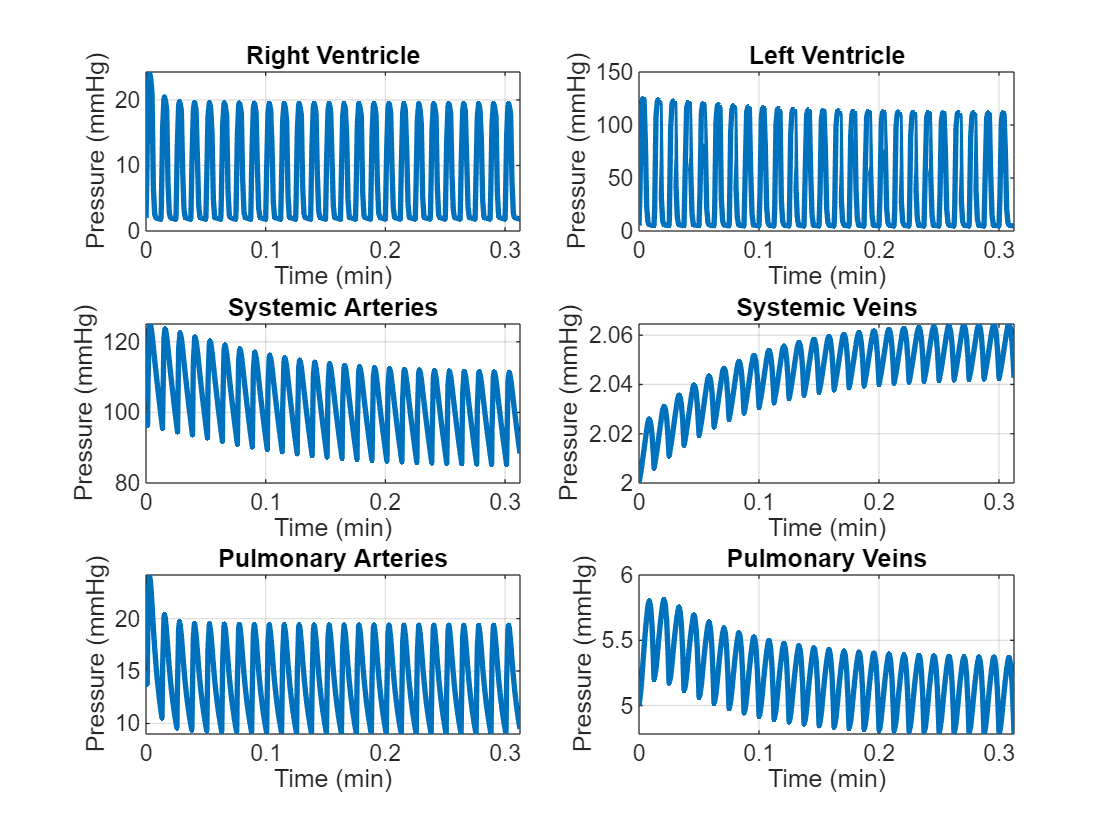

% f=gcf;
% exportgraphics(f,'Flows_Full.png','Resolution',600)

% Pressures
figure(2)
subplot(3,2,1)
plot(t,Prv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Right Ventricle');

subplot(3,2,2)
plot(t,Plv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Left Ventricle');

subplot(3,2,3)
plot(t,Psa,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Systemic Arteries');

subplot(3,2,4)
plot(t,Psv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Systemic Veins');

subplot(3,2,5)
plot(t,Ppa,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Pulmonary Arteries');

subplot(3,2,6)
plot(t,Ppv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Pulmonary Veins');

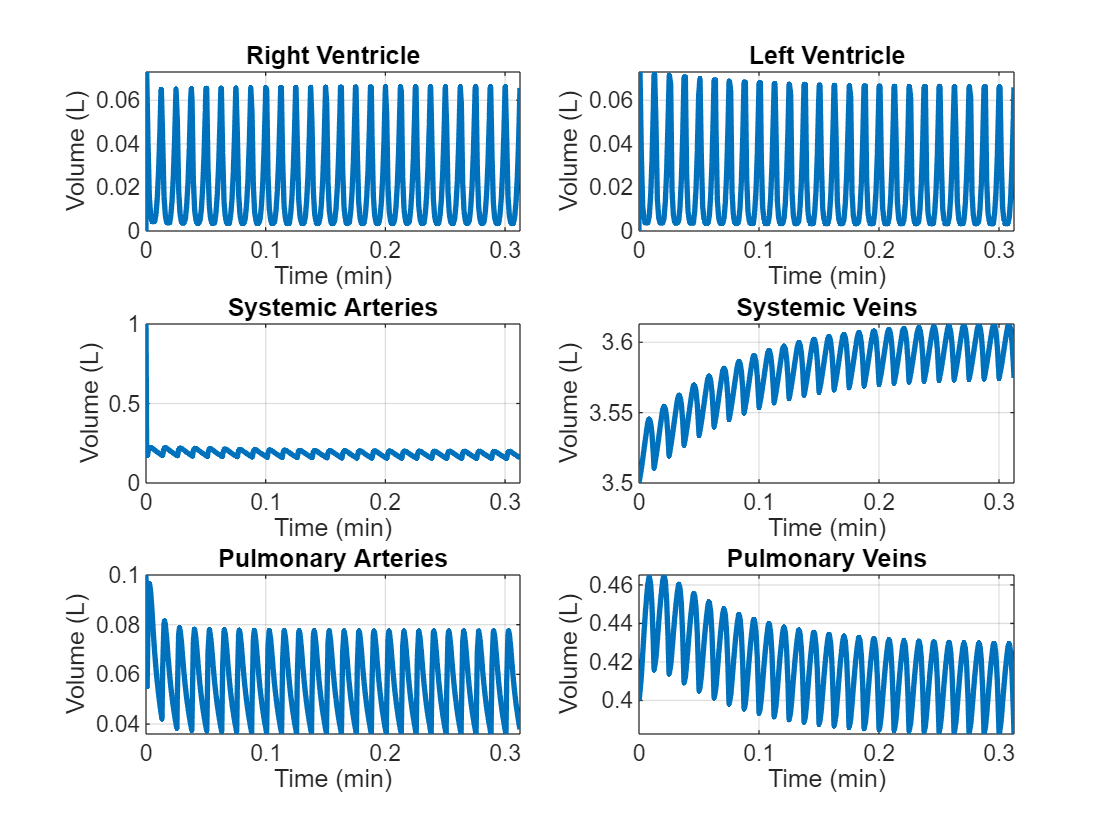

% Volumes
figure(3)
subplot(3,2,1)
plot(t,Vrv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Right Ventricle');

subplot(3,2,2)
plot(t,Vlv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Left Ventricle');

subplot(3,2,3)
plot(t,Vsa,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Systemic Arteries');

subplot(3,2,4)
plot(t,Vsv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Systemic Veins');

subplot(3,2,5)
plot(t,Vpa,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Pulmonary Arteries');

subplot(3,2,6)
plot(t,Vpv,'LineWidth',2);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Pulmonary Veins');